% Initialiser
clear; close all; clc;

% Definer Laplace-variabelen s
s = tf('s');

% Definer overføringsfunksjonen G(s) basert på oppgaven
G = 10/s * ((1+s/0.1)*(1+s/1))/((1+s/5)*(1+s/20)^2)

G =
 
      20000 s^2 + 22000 s + 2000
  ----------------------------------
  0.1 s^4 + 4.5 s^3 + 60 s^2 + 200 s
 
Continuous-time transfer function.
Model Properties


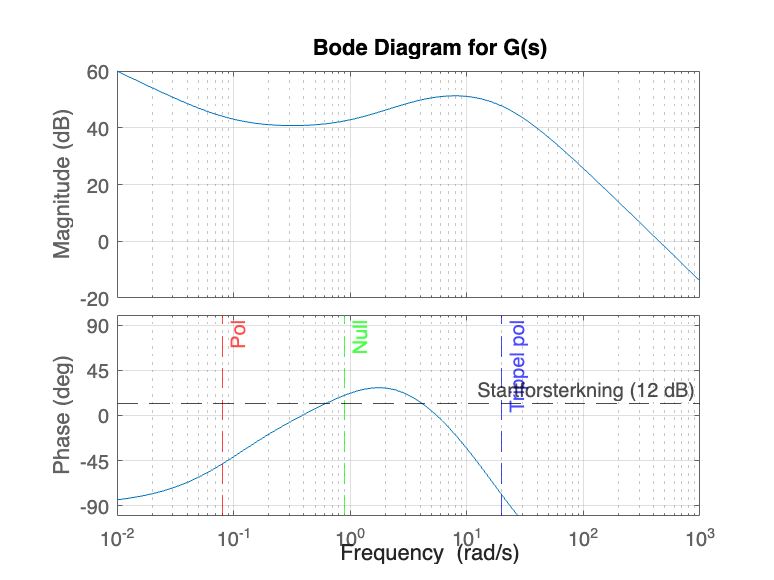


% Plot Bode-diagrammet
figure;
bode(G);
grid on;
title('Bode Diagram for G(s)');

% Sett opp akser og legg inn brytefrekvenser
hold on;
xline(0.08, '--r', 'Pol');
xline(0.9, '--g', 'Null');
xline(20, '--b', 'Trippel pol');

% Legg til en startforsterkning ved lave frekvenser
low_freq_gain_dB = 20 * log10(3.9816); % 12 dB
yline(low_freq_gain_dB, '--k', 'Startforsterkning (12 dB)');

% Juster akser for bedre visning, basert på relevante frekvenser
xlim([0.01, 1000]); % Tilpass etter ønske
ylim([-100, 100]);   % Juster for å se relevante nivåer

hold off;